# Optimal state feedback and MATLAB tools 

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state-space model. 

When a system is expressed as a state space model, it is normal to design the closed-loop compensator as a state feedback but pole placement methods were seen to be somewhat unsystematic. A more popular method is 'optimal control' because this includes some systematic tuning parameters which are intuitive to use. This file introduces the concepts concisely before showing how to use MATLAB to support this approach.

 This file gives an introduction to the topic and  relevant MATLAB code to support the associated feedback design. As ever, use text books for more detail on the theoretical aspects and MATLAB provides short cut files which can be used for efficient coding in the long  term. The file follows on from: ***state_feedback_control101***.  

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, Ross Drummond, Lanlan Su (University of Sheffield) and Ruth Bars (Budapest University of  Technology and Economics)                       

                                                                                  

## Table of Contents

1. Background on concepts of optimal state feedback

2. Examples of using lqr.m

## 1. Background on concepts of optimal state feedback

Here assume a state-space model of the form:

$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U,\;$ (1.1)

with state *X*, input *U* and output *Y. *

The target in general is to control the system behaviour and thus one adopts feedback of some form which measures the output and then makes suitable choices to the input. However, with state-space systems it is more normal to base feedback on the state rather than the output; for now assume the state is known and later resources will deal with how to estimate this. In summary, a typical state feedback takes the form:

$U=-K\;X$    (1.2)

However, the challenge is, how do we select a suitable value for K? As shown in the earlier file ***state_feedback_control101***, while it is possible to do a design based on specifying the desired closed-loop pole positions, this would normally not be used because it is difficult to make systematic choices for ALL the poles. We need a design method which automatically places the poles in sensible positions to achieve good behaviour.

Consequently, a very popular method focuses directly on optimising behaviour. A somewhat arbitrary, but nevertheless reasonable, assumption is made that behaviour can be represented quite well by the 2 norm of the deviations from the steady-state. So in the regulation case performance is defined by the following cost function:

$J=\int_0^{\infty } \left(X^T Q\;X+U^T R\;U\right)d\;t$  (1.3)

where *Q* is positive semi-definite and *R* is positive definite (see text books for explanations of this). The smaller the value for *J*, the better the performance.

**Remark**: As this resource introduces the basic concepts, it is best to focus on regulation control, that is driving the state to the origin. Later resources will introduce non-zero targets, model uncertainty and more.

It is not the purpose of this resource to give the theory, but suffice to say that with model (1.1) and performance index (1.3), it can be shown that there exists a unique optimising feedback of the form given in (1.2). This solution is found by solving the following two identities (assumes controllability ***controllability_and_observability_control101***) :

$K=-R^{-1} B^T P;\;\;\;\;\;\;A^T P+P\;A-P\;B\;R^{-1} B^T P+Q=0$  (1.4)

While one could easily create some code to solve these, unsurprisingly MATLAB has already provided code for this summarised as follows.

***[K] = lqr(SYS,Q,R)***   (Other variants of the call statement can be explored through the help)

So, define the system as a state-space object (see ***statespace_models_control101***), define the weighting matrices *Q* and *R* and then use this simple call statement to find *K*.

**Remark**: The weighting matrices *Q* and *R *are the tuning parameters. However, these are reasonably intuitive as will be demonstrated in the coding examples below.

**Remark**: Extension to the discrete-time case is straightforward, but the formula required are slightly different from (1.4) so a different file is needed. In this case use ***dlqr.m***

## 2. Examples of using lqr.m

The main interest here is to explore the choices for *Q* and* R* which underpin this design method.

### 2.1 Example 1 - impact of changing R

This example shows clearly how, as *R* is increased the input *U* becomes much less active and consequently, the states are much slower to coverge. This is as expected. By increasing the weighting in *J* on the input signal, we prioritise making that small in preference to state convergence.

disp('Section 2.1')

Section 2.1


disp('State and input trajectories with different choices of R')

State and input trajectories with different choices of R


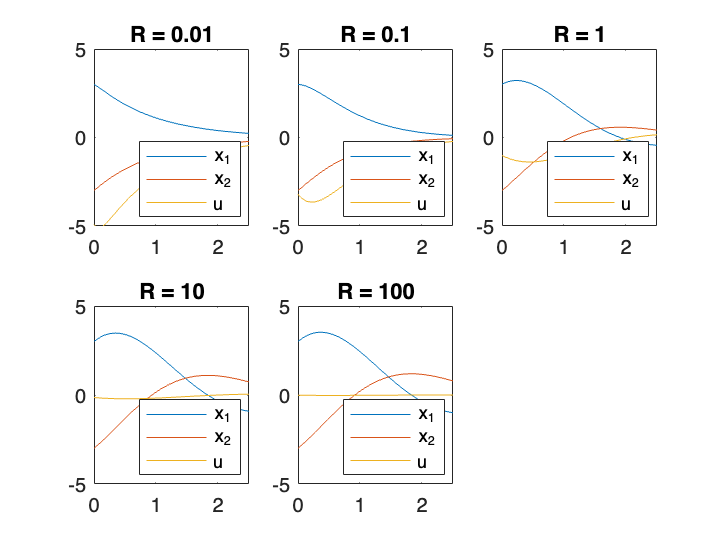

A=[-1 -2;1 0]; B=[1;0];
R=[0.01,0.1,1,10,100];
t=linspace(0,2.5,100);
u=t*0;
x0=[3;-3];
figure

for k=1:5
K=lqr(A,B,eye(2),R(k));

[y,t]=lsim(ss(A-B*K,B,[eye(2);-K],0),u,t,x0);
subplot(2,3,k);
plot(t,y); hold on
tt{k}=['R = ',num2str(R(k))];
title(tt{k})
ylim([-5 5])
xlim([0 2.5])
legend('x_1','x_2','u','Location','SouthEast')
end

### 2.2 Example 2 - impact of changing R

This example shows clearly how, as *R* is increased the input *U* becomes much less active and consequently, the states are much slower to coverge. This is as expected. By increasing the weighting in *J* on the input signal, we prioritise making that small in preference to state convergence.

disp('Section 2.2')

Section 2.2


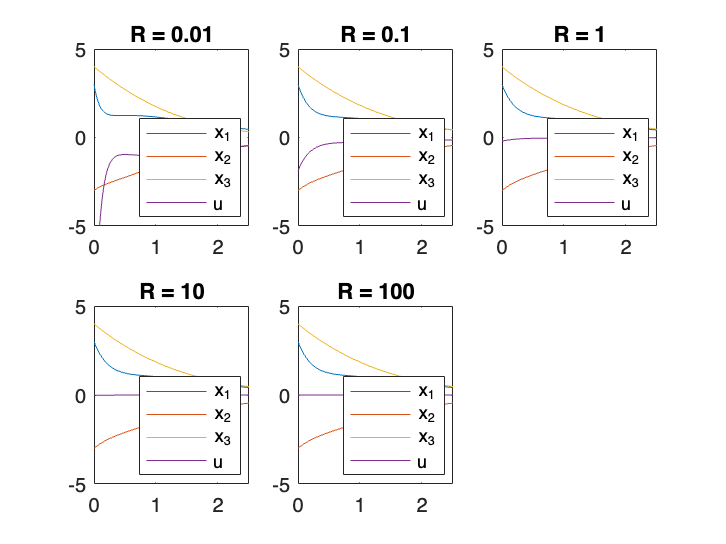

A=[-6 -11 -6;1 0 0;0 1 0]; 
B=[1;0;0];
R=[0.01,0.1,1,10,100];
t=linspace(0,2.5,100);
u=t*0;
x0=[3;-3;4];
figure
for k=1:5
K=lqr(A,B,eye(3),R(k));

[y,t]=lsim(ss(A-B*K,B,[eye(3);-K],0),u,t,x0);
subplot(2,3,k);
plot(t,y); hold on
tt{k}=['R = ',num2str(R(k))];
title(tt{k})
ylim([-5 5])
xlim([0 2.5])
legend('x_1','x_2','x_3','u','Location','SouthEast')
end

### 2.3 Example 3 - impact of changing R with a discrete-time example

This example shows clearly how, as *R* is increased the input *U* becomes much less active and consequently, the states are much slower to converge. This is as expected. By increasing the weighting in *J* on the input signal, we prioritise making that small in preference to state convergence. Note we have used*** dlqr.m*** here as this is a discrete case.

disp('Section 2.3')

Section 2.3


disp('State trajectories with different choices of R: discrete case')

State trajectories with different choices of R: discrete case


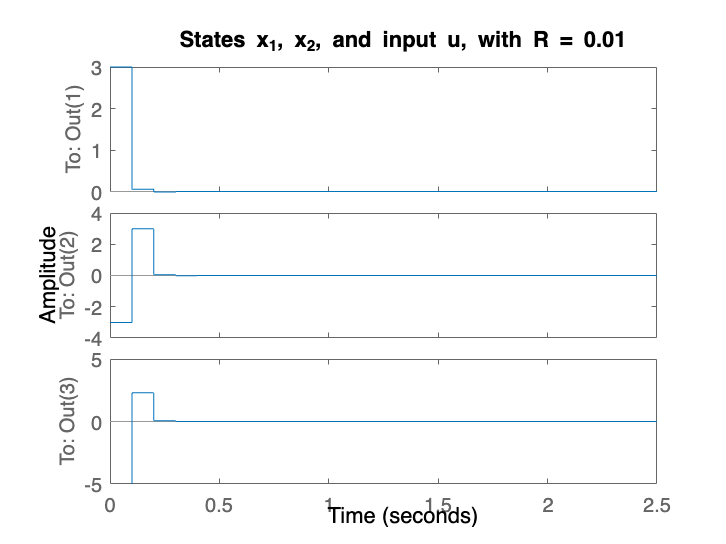

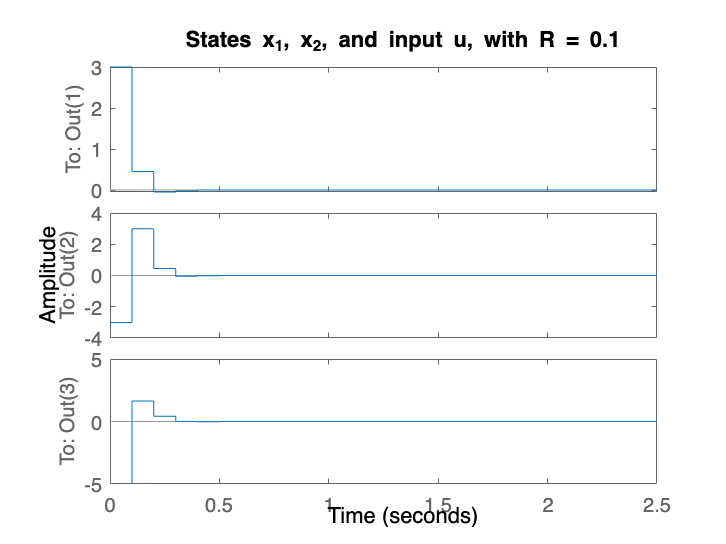

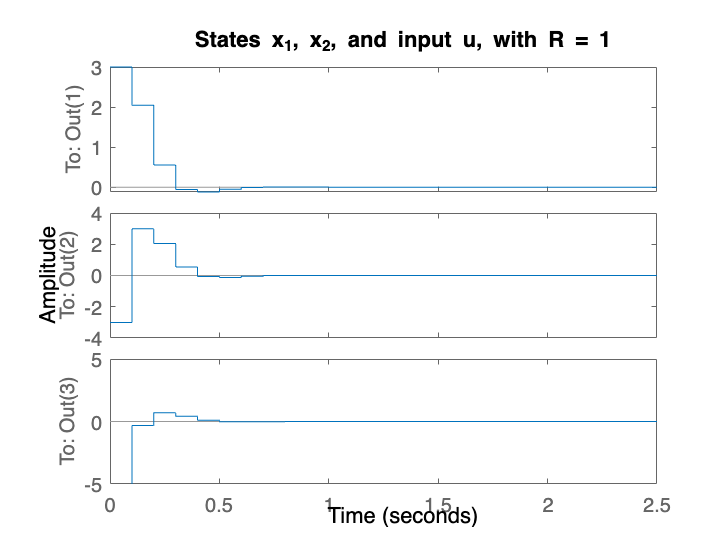

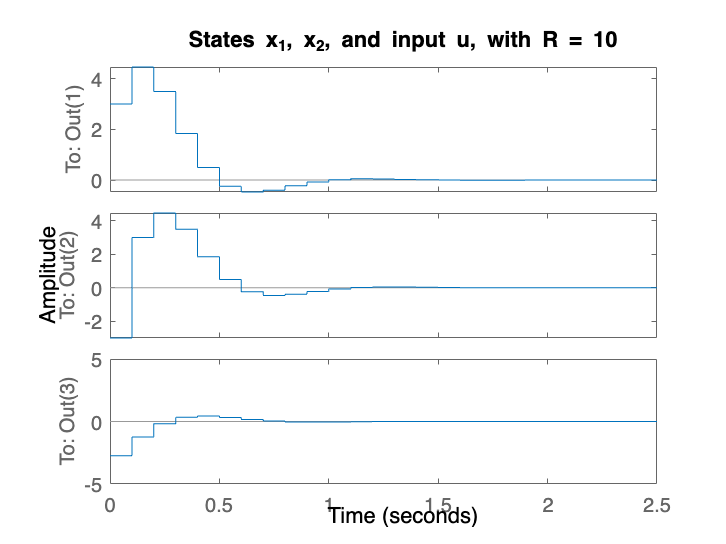

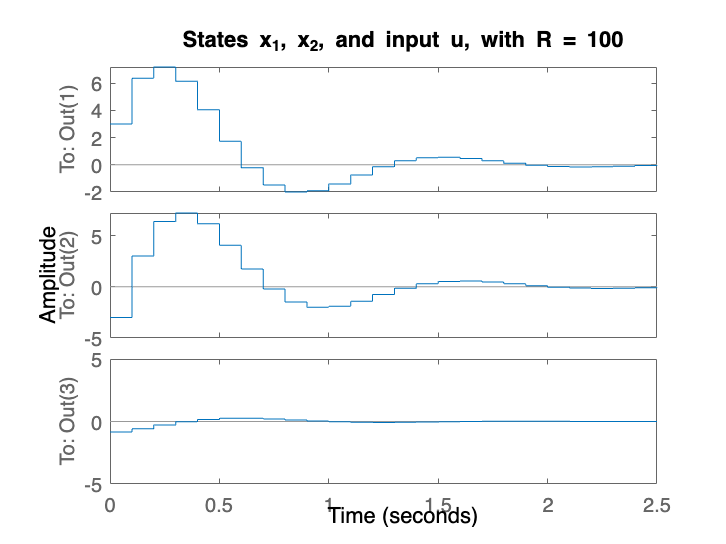

A=[1.6 -0.8;1 0]; B=[1;0];
R=[0.01,0.1,1,10,100];
Tsamp=0.1;
t=0:Tsamp:2.5;
u=0*t;
x0=[3;-3];

c=[1 0 0;0 1 0; 0 0 1; 0 0 0; 1 0 1];
for k=1:5
K=dlqr(A,B,eye(2),R(k));

figure
lsim(ss(A-B*K,B,[eye(2);-K],0,0.1),u,t,x0);
tt{k}=['States x_1, x_2, and input u, with R = ',num2str(R(k))];
title(tt{k})
ylim([-5 5])
xlim([0 2.5])
%legend('x_1','x_2','u','Location','SouthEast')
end

### 2.4 Example 4 - impact of changing Q

Given that both the weights appear in the performance index one can change the overall relative sizing by just changing one of these. Of course, *Q* and *R* are matrices so it is possible to offer more nuanced variations in the priorities, for example to prioritise one state over another state. In practice this could quite messy and is not as systematic as one might like, but we illustrate the potential here for completeness. It is interesting to note that the impact of changing individual values of *Q* may not be as significant as one had hoped, and perhaps that simply means that the states are all inter-related and thus it is difficult to control the dynamics independently of each other with an otherwise sensible state feedback.

disp('Section 2.4 - impact of changing Q')

Section 2.4 - impact of changing Q


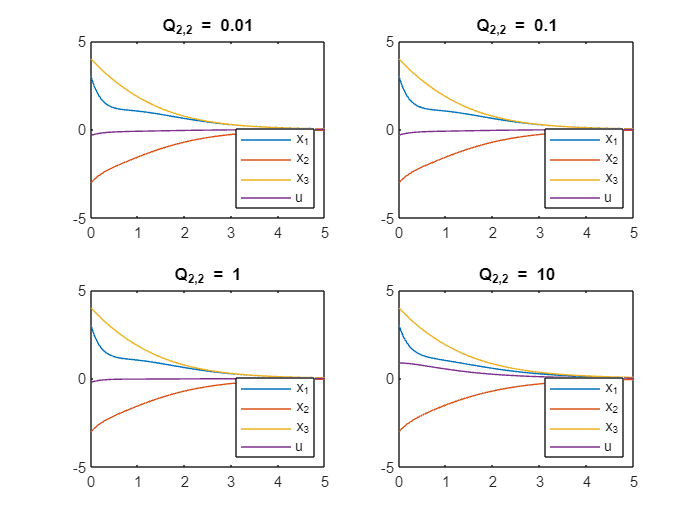

A=[-6 -11 -6;1 0 0;0 1 0]; 
B=[1;0;0];
R=[1];
q=[0.01 0.1 1 10];
t=linspace(0,5,100);
u=t*0;
x0=[3;-3;4];
figure
for k=1:4
Q = diag([1,q(k),1]);
K=lqr(A,B,Q,R);

[y,t]=lsim(ss(A-B*K,B,[eye(3);-K],0),u,t,x0);
subplot(2,2,k);
plot(t,y); hold on
tt{k}=['Q_{2,2} = ',num2str(q(k))];
title(tt{k})
ylim([-5 5])
xlim([0 5])
legend('x_1','x_2','x_3','u','Location','SouthEast')
end